# Exercice n°3

clc
clear

load("ws_homework_3_2025.mat")

Ts=1e-3; %sample time
mass = 1.5; % Kg
g = 9.81; %m/s^2
e_3 = [0 0 1]';
Ib = diag([1.2416 1.2416 2*1.2416]); % inertia matrix
t = thrust.time(:,1); % time
n = size(t,1); % number of elements
T_f = t(n,1);

% Skew matrix computation
function S = skew(v)
    if(numel(v)~= 1)
        S= [0 -v(3) v(2); 
            v(3) 0 -v(1);
            -v(2) v(1) 0];
    else
        S= zeros(3);
    end
end

function Q_matrix = Q(i,rho,theta)
    Q_matrix = [1 0 -sin(theta(i));
        0 cos(rho(i)) cos(theta(i))*sin(rho(i));
        0 -sin(rho(i)) cos(theta(i))*cos(rho(i))];
end

function Q_dot_matrix = Q_dot(i,rho,theta,eta_dot)
    Q_dot_matrix = [0 0 -cos(theta(i))*eta_dot(2,i);
        0 -sin(rho(i))*eta_dot(1,i) (-sin(theta(i))*eta_dot(2,i)*sin(rho(i))+cos(theta(i))*cos(rho(i))*eta_dot(1,i));
        0 -cos(rho(i))*eta_dot(1,i) (-sin(theta(i))*eta_dot(2,i)*cos(rho(i))-cos(theta(i))*sin(rho(i))*eta_dot(1,i))];
end

function R_matrix = Rb(i,rho,theta,psi)
    R_matrix = [cos(theta(i))*cos(psi(i)) (sin(rho(i))*sin(theta(i))*cos(psi(i))-cos(rho(i))*sin(psi(i))) (cos(rho(i))*sin(theta(i))*cos(psi(i))+sin(rho(i))*sin(psi(i)));
            cos(theta(i))*sin(psi(i)) (sin(rho(i))*sin(theta(i))*sin(psi(i))+cos(rho(i))*cos(psi(i))) (cos(rho(i))*sin(theta(i))*sin(psi(i))-sin(rho(i))*cos(psi(i)));
            -sin(theta(i)) sin(rho(i))*cos(theta(i)) cos(rho(i))*cos(theta(i))];
end

% Computation of a transfer function such that is a low-pass filter that
% has a high cutting frequency to pass almost every signal but with not
% to much noise

r = 2; % order
w_c = 40; % cutting frequency [rad/s] (the value must be high)

syms s
den_s = expand((s + w_c)^r); %denominator of the filter transfer function 
c_sym = coeffs(den_s,s,"All");
c = double(fliplr(c_sym(2:end)));

K = zeros(1,r); %K_i coefficients
K(r) = c(end);
for i = r-1:-1:1
    prodK_next = prod(K(i+1:end));
    K(i) = c(i)/prodK_next;
end

% disp('Filter poles:');
% disp(pole(G_i));
% 
% % Frequency response
% figure;
% bode(G_i);
% title(['Bode plot of Butterworth filter of order ', num2str(r)]);
% grid on;
% 
% % Step response
% figure;
% step(G_i);
% title(['Step response of Butterworth filter of order ', num2str(r)]);
% xlabel('Time [s]');
% ylabel('Magnitude');

% Estimated external wrench initialization
wrench_ext_est = zeros(n,6);
gamma = zeros(n,6,r);
f_next = 0; %integral term
f_int = zeros(n,6,r);
mass_est = zeros(n,1);

rho = attitude.signals.values(:,1); %roll
theta = attitude.signals.values(:,2); %pitch
rho = attitude.signals.values(:,1); %roll
theta = attitude.signals.values(:,2); %pitch
psi = attitude.signals.values(:,3); %yaw
eta = attitude.signals.values(:,:)';
eta_dot = attitude_vel.signals.values(:,:)';
p_b_dot = linear_vel.signals.values(:,:)';
uT = thrust.signals.values(:,:)';
tau_b = tau.signals.values(:,:)';
for i=1:n-1%n-1
 
    % Computation of the rotation matrix in the body frame
    Rb_next = Rb(i+1,rho,theta,psi);

    % Computation of the Coriolis matrix
    Q_next = Q(i+1,rho,theta);
    Q_dot_next = Q_dot(i+1,rho,theta,eta_dot);
    C_next = Q_next'*skew(Q_next*eta_dot(:,i+1))*Ib*Q_next+Q_next'*Ib*Q_dot_next;
    
    % Computation of the mass matrix
    M_next = Q_next'*Ib*Q_next;
    Q_act = Q(i,rho,theta);
    M = Q_act'*Ib*Q_act;
    
    % Computation of the actual momentum
    q_next = [mass*eye(3) zeros(3); zeros(3) M_next]*[p_b_dot(:,i+1); eta_dot(:,i+1)];
    q = [mass*eye(3) zeros(3); zeros(3) M]*[p_b_dot(:,i); eta_dot(:,i)];
    
    %gamma_1
    K_1 = K(1);
    if i > 1
        f_next = (wrench_ext_est(i,:)'+[mass*g*e_3-uT(1,i+1)*Rb_next*e_3; C_next'*eta_dot(:,i+1)+Q_next'*tau_b(:,i+1)])'; %integral term of gamma_1 (1x6)
        f_int(i+1,:,1) = f_int(i,:,1) + Ts*f_next; %integration with backward Eulero (1x6)
    end
    gamma(i,:,1) = K_1*(q-f_int(i+1,:,1)')'; %gamma_1 (1x6) 

    if r > 1
        for j = 2:r
            K_j = K(j);
            if i > 1
                f_next = -wrench_ext_est(i,:)+gamma(i,:,j-1); %integral term of gamma_j
                f_int(i+1,:,j) = f_int(i,:,j) + Ts*f_next;
            end
            gamma(i,:,j) = K_j*f_int(i+1,:,j);
        end
    end

    wrench_ext_est(i+1,:)=gamma(i,:,r);

    %mass estimation of the UAV from the estimated disturbance along the z-axis
    mass_est(i,1) = (uT(1,i)*e_3'*Rb(i,rho,theta,psi)*e_3+wrench_ext_est(i,3))/g;
end

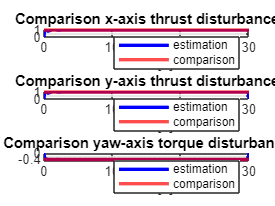

dist_x = 1; %N
dist_y = 1; %N
dist_yaw = -0.4; %Nm

figure;

subplot(3, 1, 1);
plot(t,wrench_ext_est(:,1),'b', 'LineWidth', 2)
hold on;
yline(dist_x, 'r', 'LineWidth', 2);
grid on;
xlabel('Time [s]');
ylabel('Thrust [N]');
title('Comparison x-axis thrust disturbance');
legend('estimation', 'comparison');

subplot(3, 1, 2);
plot(t,gamma(:,2,r),'b', 'LineWidth', 2)
hold on;
yline(dist_y, 'r', 'LineWidth', 2);
grid on;
xlabel('Time [s]');
ylabel('Thrust [N]');
title('Comparison y-axis thrust disturbance');
legend('estimation', 'comparison');

subplot(3, 1, 3);
plot(t,gamma(:,6,r),'b', 'LineWidth', 2)
hold on;
yline(dist_yaw, 'r', 'LineWidth', 2);
grid on;
xlabel('Time [s]');
ylabel('Torque [Nm]');
title('Comparison yaw-axis torque disturbance');
legend('estimation', 'comparison');

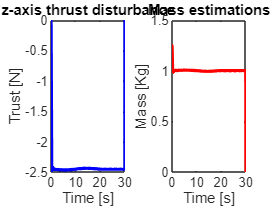


figure;
subplot(1, 2, 1);
plot(t,gamma(:,3,r),'b', 'LineWidth', 2)
hold on;
xlabel('Time [s]');
ylabel('Trust [N]');
title('z-axis thrust disturbance');
subplot(1, 2, 2);
plot(t,mass_est,'r', 'LineWidth', 2)
xlabel('Time [s]');
ylabel('Mass [Kg]');
title('Mass estimations');